# **2 - INTEREST RATES BOOTSTRAP**

## **EXERCISE 1: **Bootstrap for Euribor 3M Interbank curve:

Considering the inter-bank market on the 15th of February 2008 at 10:45 C.E.T. Implement the code necessary to realize the bootstrap for the Discount Factors' curve (with a single-curve model). Output values should be on settlement date and expires of quoted underlings. Hints: include in the datesSet of the bootstrap only end dates of underlying contracts.

### **SETUP**

% Initialize workspace
clc; clear; close all;

% Fix randomness
rng('default');   

% Add shared library folder
addpath(genpath(fullfile('..','..','lib')));

% Add project-specific folders
addpath(genpath('src'));
addpath(genpath('data'));
addpath(genpath('results'));

% Define paths
resultsPath = fullfile('results');
figuresPath = fullfile('results', 'figures');
srcPath = fullfile('src');
dataRawPath = fullfile('data', 'raw');
dataInterimPath = fullfile('data', 'interim');
dataProcessedPath = fullfile('data', 'processed');

### **UPLOAD DATA**

filename = fullfile(dataRawPath, 'MktData_CurveBootstrap');
dateFormat = 'dd/MM/yyyy';
[datesSet, ratesSet] = ReadExcelData(filename, dateFormat);

### **POINT A**

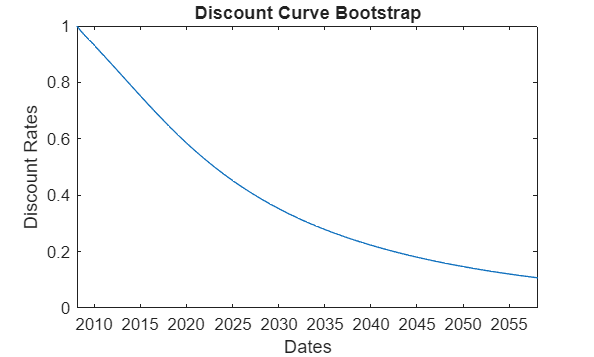

[dates, discounts] = Bootstrap(datesSet, ratesSet);
% plot
figure; 
plot(dates, discounts);
xlabel('Dates');
ylabel('Discount Rates');
title('Discount Curve Bootstrap');
